# Assignment 1

## Question 1 - Electron Modelling

clc; close all; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')


#### Simulation Setup

eCount = 1000;      % Total number of electrons
ePlotted = 15;      % Number of Electrons Plotted
dt = 10e-15;        % Time step 10fs -> ( -(Width/100) / vT )
nt = 200;           % Number of time steps
tStop = nt * dt;    % Stop Time


#### Region settings

Width = 200e-9;
Height = 100e-9;


#### Electron Properties

kB = 1.38066e-23;   % J/K 
m0 = 9.11e-31;      % Rest Mass
mn = 0.26*m0;       % Effective Mass


#### Thermal Velocity (1.1)

Temp = 300;     % K
vT = sqrt((2*kB*Temp)/mn);
fprintf("Thermal Velocity: vth = %d m/s\n", vT);

Thermal Velocity: vth = 1.870136e+05 m/s


#### Mean Free Path (1.2)

tmin = 0.2e-12;
mfp = vT * tmin;    % Mean Free Path
fprintf("Mean Time Between Collision: tmin = %d s\n", tmin);

Mean Time Between Collision: tmin = 2.000000e-13 s


fprintf("Nominal Mean Free Path = %d m\n", mfp);

Nominal Mean Free Path = 3.740272e-08 m


#### Initializing all Electrons

**All electron properties are stored in a structure called _eObj._**

- **A random position is assigned**

- **A constant velocity relative to the thermal velocity is assigned**

% Electron Object Classification
eObj = struct('x', 0, 'y', 0, 'vx', 0, 'vy', 0, 'vm', 0);
eCol = rand(eCount,3);   % Random colours for plotting
for i = 1 : eCount
    eObj(i).x = rand()*Width;
    eObj(i).y = rand()*Height;
    eObj(i).vx = sqrt(vT^2 / 2) * (2*randi([0 1])-1);
    eObj(i).vy = sqrt(vT^2 / 2) * (2*randi([0 1])-1);
    eObj(i).vm = sqrt(eObj(i).vx^2 + eObj(i).vy^2);
end


### Main Loop

**Iterating through time, each time step cycles through each electron, **

**performing certain manipulations and conditional checks.**

**It is acknowledged that the process is extremely ineffiecient and **

**could be resolved using MATLAB's built-in vector logic.**

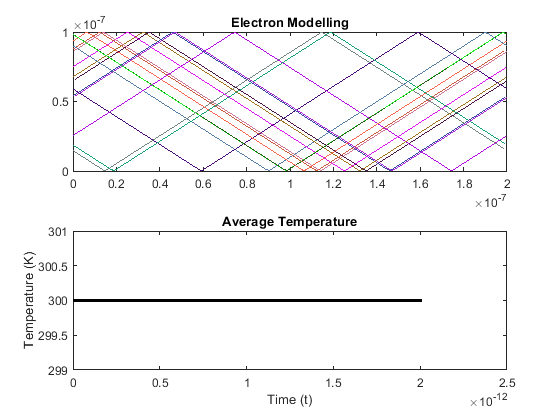


t = 0;          % Init time
counter = 2;    % Init Counter
while t < tStop
    t = t + dt; % Incrementing Time
    for i = 1 : eCount
        
        % Updating position
        eObj(i).x(counter) = eObj(i).x(counter-1) + eObj(i).vx * dt;
        eObj(i).y(counter) = eObj(i).y(counter-1) + eObj(i).vy * dt;
        
        % Magnitude of velocity
        eObj(i).vm = sqrt(eObj(i).vx.^2 + eObj(i).vy.^2);
        
        % Top and Bottom Boundary Conditions
        if eObj(i).y(counter) > Height % y = 200nm boundary 
            diff = eObj(i).y(counter) - Height;
            eObj(i).y(counter) = Height - diff;
            eObj(i).vy = -eObj(i).vy;
        end
        if eObj(i).y(counter) < 0   % y = 0nm boundary
            diff = -eObj(i).y(counter);
            eObj(i).y(counter) = diff;
            eObj(i).vy = -eObj(i).vy;
        end
        
        % Plotting Electrons
        if (i <= ePlotted)
            subplot(2,1,1)  % Plotting previous and current position
            p = plot( [eObj(i).x(counter-1), eObj(i).x(counter)], ...
                [eObj(i).y(counter-1), eObj(i).y(counter)] );
            p.Color = eCol(i,:);        % Giving a unique colour to each
            axis([0,Width,0,Height]);	% Plot Axis' set
            title('Electron Modelling');
            hold on
        end
        
        % Left hand and Right hand side Boundary Conditions
        if eObj(i).x(counter) > Width   % x = 100nm boundary
            eObj(i).x(counter) = eObj(i).x(counter) - Width;
        end
        if eObj(i).x(counter) < 0   % x = 0nm boundary
            eObj(i).x(counter) = eObj(i).x(counter) + Width;
        end
        
    end
    pause(0.05);	% Delay for animation
    
    % Plotting the Average Temperature over time
    Time(:,counter) = t;
    % Calculating the temperature from the magnitude of velocity
    allTemperatures = ( ([eObj(:).vm].^2) .* mn ) ./ (kB*2);
    Temp(:,counter) = mean(allTemperatures);    % Average Temperatures
    subplot(2,1,2), plot(Time, Temp, 'k', 'LineWidth',1.75)
    ylim([299,301]), xlabel('Time (t)'), ylabel('Temperature (K)')
    title('Average Temperature');

    counter = counter + 1;      % Incrementing Sim Counter
end
hold off

## Question 2 - Collisions with Mean Free Path

Scattering is enabled.

#### Scattering Settings

toggleScatter = 1;                  % Toggle Scattering OFF(0) ON(1)
pScatter = 1 - exp(-dt/tmin);       % Probability of scatter event
scatterTracker = zeros(nt, eCount); % Tracking the scatter events


#### **Re-Initializing all Electrons**

- **A random position is assigned**

- **A random velocity relative to the thermal velocity is assigned**

% Electron Object Classification
eObj = struct('x', 0, 'y', 0, 'vx', 0, 'vy', 0, 'vm', 0);
eCol = rand(eCount,3);   % Random colours for plotting
for i = 1 : eCount
    eObj(i).x = rand()*Width;
    eObj(i).y = rand()*Height;
    eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vm = sqrt(eObj(i).vx^2 + eObj(i).vy^2);
end

### Main Loop for Q2 similar to Q1

**Iterating through time, each time step cycles through each electron, **

**performing certain manipulations and conditional checks.**

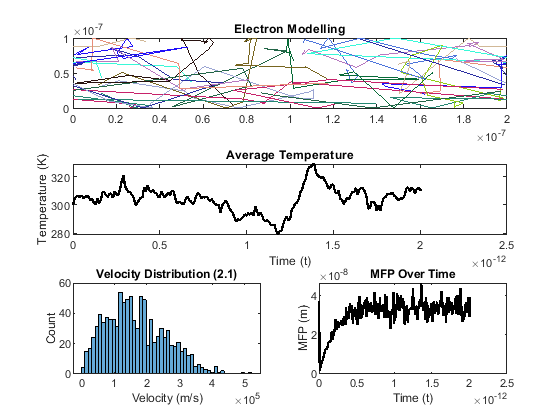

t = 0;          % Init time
Time = 0;       % Vector that accumulates time
Temp = 300;     % Vector that accumulates temperature
counter = 2;    % Init Counter
while t < tStop
    t = t + dt;     % Incrementing Time
    for i = 1 : eCount
        
        % Updating position
        eObj(i).x(counter) = eObj(i).x(counter-1) + eObj(i).vx * dt;
        eObj(i).y(counter) = eObj(i).y(counter-1) + eObj(i).vy * dt;
        
        % Scattering effect - Randomize direction/magnitude of velocity
        % Probability of scattering based on p.
        if pScatter > rand() && toggleScatter	% 'if true'
            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
            scatterTracker(counter,i) = t;
        else
            scatterTracker(counter,i) = scatterTracker(counter-1,i);
        end
        
        % Magnitude of velocity
        eObj(i).vm = sqrt(eObj(i).vx.^2 + eObj(i).vy.^2);
        
        % Top and Bottom Boundary Conditions
        if eObj(i).y(counter) > Height % y = 200nm boundary 
            diff = eObj(i).y(counter) - Height;
            eObj(i).y(counter) = Height - diff;
            eObj(i).vy = -eObj(i).vy;
        end
        if eObj(i).y(counter) < 0   % y = 0nm boundary
            diff = -eObj(i).y(counter);
            eObj(i).y(counter) = diff;
            eObj(i).vy = -eObj(i).vy;
        end
        
        % Plotting Electrons
        if (i <= ePlotted)
            subplot(3,1,1)  % Plotting previous and current position
            p = plot( [eObj(i).x(counter-1), eObj(i).x(counter)], ...
                [eObj(i).y(counter-1), eObj(i).y(counter)] );
            p.Color = eCol(i,:);        % Giving a unique colour to each
            axis([0,Width,0,Height]);	% Plot Axis' set
            title('Electron Modelling');
            hold on
        end
        
        % Left hand and Right hand side Boundary Conditions
        if eObj(i).x(counter) > Width   % x = 100nm boundary
            eObj(i).x(counter) = eObj(i).x(counter) - Width;
        end
        if eObj(i).x(counter) < 0   % x = 0nm boundary
            eObj(i).x(counter) = eObj(i).x(counter) + Width;
        end
        
    end
    pause(0.01);	% Delay for animation
    
    % Plotting the Average Temperature over time
    % Overtime the average temperature varies around the set value (2.3)
    Time(:,counter) = t;
    allTemperatures = ( ([eObj(:).vm].^2) .* mn ) ./ (kB*2);
    Temp(:,counter) = mean(allTemperatures); % Average Temperature
    subplot(3,1,2), plot(Time, Temp, 'k', 'LineWidth',1.75);
    xlabel('Time (t)'), ylabel('Temperature (K)')
    title('Average Temperature');
    
    % Plotting the distribution of velocities (2.1)
    subplot(3,2,5), histogram([eObj(:).vm],50);
    xlabel('Velocity (m/s)'), ylabel('Count');
    title('Velocity Distribution (2.1)');
    
    % Plotting the MEAN FREE PATH over time (2.4)
    timeScatter = scatterTracker(counter,:)-scatterTracker(counter-1,:);
    mfp(:,counter) = mean([eObj(:).vm])*mean(timeScatter(timeScatter>0));
    subplot(3,2,6), plot(Time, mfp, 'k', 'LineWidth',1.75)
    xlabel('Time (t)'), ylabel('MFP (m)'), title('MFP Over Time');
    
    counter = counter + 1;      % Incrementing Sim Counter
end
hold off

## Question 3 - Enhancements

Scattering is enabled and box colliders have been added.

On collision with a box the particle re-thermalizes.

There is a setting to change the interaction to a specular one.

### Bottlenecking Settings

% Addition of box colliders to the sim
toggleDiffusive = 1; % 0 - Specular, 1 - Diffusive
% Providing opposing corners of desired boxes
% Multiple boxes can be simply appeded to the box array
box = [ % x1,y1, x2, y2 (Per box)
    0.8, 0, 1.2, 0.4;
    0.8, 0.6, 1.2, 1;
    ].*1e-7;


#### **Re-Initializing all Electrons**

- **A random position is assigned**

- **A random velocity relative to the thermal velocity is assigned**

% Electron Object Classification
eObj = struct('x', 0, 'y', 0, 'vx', 0, 'vy', 0, 'vm', 0);
eCol = rand(eCount,3);   % Random colours for plotting
for i = 1 : eCount
    eObj(i).x = rand()*Width;
    eObj(i).y = rand()*Height;
    for b = 1:size(box,1)   % Preventing electron from starting in box
        while eObj(i).x <= max(box(b,1),box(b,3)) && ...
        eObj(i).x >= min(box(b,1),box(b,3)) && ...
        eObj(i).y <= max(box(b,2),box(b,4)) && ...
        eObj(i).y >= min(box(b,2),box(b,4))
            eObj(i).x = rand()*Width;
            eObj(i).y = rand()*Height;
        end
    end
    eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vm = sqrt(eObj(i).vx^2 + eObj(i).vy^2);
end


### Main Loop for Q3 again similar to previous

**Iterating through time, each time step cycles through each electron, **

**performing certain manipulations and conditional checks.**

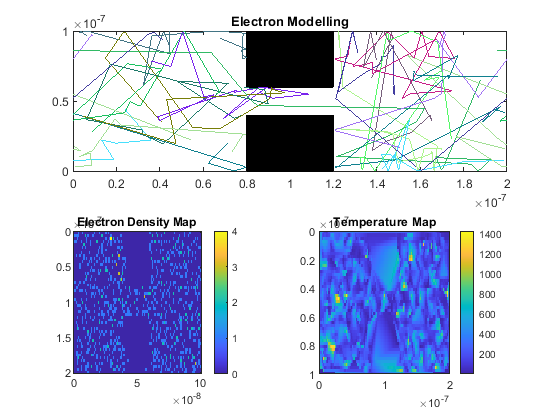

t = 0;          % Init time
counter = 2;    % Init Counter
while t < tStop
    xVect = 0;
    yVect = 0;
    t = t + dt; % Incrementing Time
    for i = 1 : eCount
        
        % Updating position
        xVect(i) = eObj(i).x(counter-1) + eObj(i).vx * dt;
        yVect(i) = eObj(i).y(counter-1) + eObj(i).vy * dt;
        eObj(i).x(counter) = xVect(i);
        eObj(i).y(counter) = yVect(i);
        
        % Scattering effect - Randomize direction/magnitude of velocity
        % Probability of scattering based on p.
        if pScatter > rand() && toggleScatter	% 'if true'
            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
        end
        
        % Magnitude of velocity
        eObj(i).vm = sqrt(eObj(i).vx.^2 + eObj(i).vy.^2);

        
        % Box Collider Conditions. Iterating through each defined box.
        for b = 1:size(box,1)
            % Plotting the Boxes on the plot
            if counter == 2 % Only plot once
                boxX = [box(b,1), box(b,1), box(b,3), box(b,3), box(b,1)];
                boxY = [box(b,2), box(b,4), box(b,4), box(b,2), box(b,2)];
                fill(boxX, boxY, 'k');
            end
            
            % Boundaries defined by coordinates
            boundL = min(box(b,1),box(b,3));    % Left Wall
            boundR = max(box(b,1),box(b,3));    % Right Wall
            boundT = max(box(b,2),box(b,4));    % Top Wall
            boundB = min(box(b,2),box(b,4));    % Bottom Wall
            
            % Conditions set by boundaires
            condL = eObj(i).x(counter-1) <= boundL && ... 
                    eObj(i).x(counter) >= boundL;   % Left
            condR = eObj(i).x(counter-1) >= boundR && ...
                    eObj(i).x(counter) <= boundR;   % Right
            condB = eObj(i).y(counter-1) <= boundB && ...
                    eObj(i).y(counter) >= boundB;   % Bottom
            condT = eObj(i).y(counter-1) >= boundT && ...
                    eObj(i).y(counter) <= boundT;   % Top
            
            % Corner Cases
            condTC = condT && condR || condT && condL;
            condBC = condB && condR || condB && condL;
            
            % Checking Left and Right of the of the box collider First. 
            % Start by confirming if within Top and Bottom Boundaries
            if eObj(i).y(counter) <= boundT && eObj(i).y(counter) >=boundB
                if condL || condR || condTC || condBC
                    if toggleDiffusive == 1 % If diffusion is toggled
                        posX = eObj(i).vx >= 0;	% Storing sign
                        posY = eObj(i).vy >= 0;
                        % re-thermalizing
                        eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                        eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                        % checking sign
                        if (eObj(i).vx >= 0) == posX
                            eObj(i).vx = -eObj(i).vx;
                        end
                        if (eObj(i).vy >= 0) ~= posY
                            eObj(i).vy = -eObj(i).vy;
                        end
                    else
                        eObj(i).vx = -eObj(i).vx;   % Just inverting
                    end
                    if condL    % Shifting reflection point
                        eObj(i).x(counter) = boundL - ...
                            (eObj(i).x(counter) - boundL);
                    else
                        eObj(i).x(counter) = boundR + ...
                            (boundR - eObj(i).x(counter));
                    end
                end
            end
            
            % Checking Top and Bottom of the box collider. 
            % Start by confirming if within Left and Right Boundaries
            if eObj(i).x(counter) <= boundR && eObj(i).x(counter) >=boundL
                if condT || condB
                    if toggleDiffusive == 1
                        posX = eObj(i).vx >= 0;
                        posY = eObj(i).vy >= 0;  % Storing sign
                        % re-thermalizing
                        eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                        eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                        % checking sign
                        if (eObj(i).vx >= 0) ~= posX
                            eObj(i).vx = -eObj(i).vx;
                        end
                        if (eObj(i).vy >= 0) == posY
                            eObj(i).vy = -eObj(i).vy;
                        end
                    else
                        eObj(i).vy = -eObj(i).vy;
                    end
                    if condB    % Shifting reflection point
                        eObj(i).y(counter) = boundB - ...
                            (eObj(i).y(counter) - boundB);
                    else
                        eObj(i).y(counter) = boundT + ...
                            (boundT - eObj(i).y(counter));
                    end
                end
            end
        end
        
        
        % Top and Bottom Boundary Conditions
        if eObj(i).y(counter) > Height % y = 200nm boundary 
            diff = eObj(i).y(counter) - Height;
            eObj(i).y(counter) = Height - diff;
            eObj(i).vy = -eObj(i).vy;
        end
        if eObj(i).y(counter) < 0   % y = 0nm boundary
            diff = -eObj(i).y(counter);
            eObj(i).y(counter) = diff;
            eObj(i).vy = -eObj(i).vy;
        end
        
        % Plotting Electrons
        if (i <= ePlotted)
            subplot(2,1,1)  % Plotting previous and current position
            p = plot( [eObj(i).x(counter-1), eObj(i).x(counter)], ...
                [eObj(i).y(counter-1), eObj(i).y(counter)] );
            p.Color = eCol(i,:);        % Giving a unique colour to each
            axis([0,Width,0,Height]);	% Plot Axis' set
            title('Electron Modelling');
            hold on
        end
        
        % Left hand and Right hand side Boundary Conditions
        if eObj(i).x(counter) > Width   % x = 100nm boundary
            eObj(i).x(counter) = eObj(i).x(counter) - Width;
        end
        if eObj(i).x(counter) < 0   % x = 0nm boundary
            eObj(i).x(counter) = eObj(i).x(counter) + Width;
        end
        
    end
    pause(0.00001);	% Delay for animation
    
    % Plotting an Electron Density map (3.3)
    ptsX = linspace(0, Width, 100);
    ptsY = linspace(0, Height, 50);
    N = histcounts2(yVect, xVect, ptsY, ptsX);  % Binning the positons
    subplot(2, 2, 3);
    imagesc(ptsY,ptsX,N),colorbar,title('Electron Density Map');
    
    
    % Plotting Temperature Map (3.4)
    allTemperatures = ( ([eObj(:).vm].^2) .* mn ) ./ (kB*2);
    xv = linspace(min(xVect), max(xVect), 100);
    yv = linspace(min(yVect), max(yVect), 50);
    [X,Y] = meshgrid(xv, yv);
    Z = griddata(xVect,yVect,allTemperatures,X,Y);  % Mapping Temps
    subplot(2, 2, 4);
    imagesc(xv,yv,Z),colorbar,title('Temperature Map');
    axis([0,Width,0,Height]);  % Plot Axis' set
    
    counter = counter + 1;      % Incrementing Sim Counter
end
hold off

Collision with box functions a majority of the time. Note on the density map 

some electrons can penetrate near the inside corners of the boxes. The electron 

presumably bounced off the wall and then through the barrier. The corner cases are 

handled; however, more work is required to prevent bugs.

Other indications of electrons in a box are artifacts of the binning for the 

density map. Adjacent positons are combined which can look like an electron has 

gone through.